Create JS and data for all patients and sides 

PT1 Right

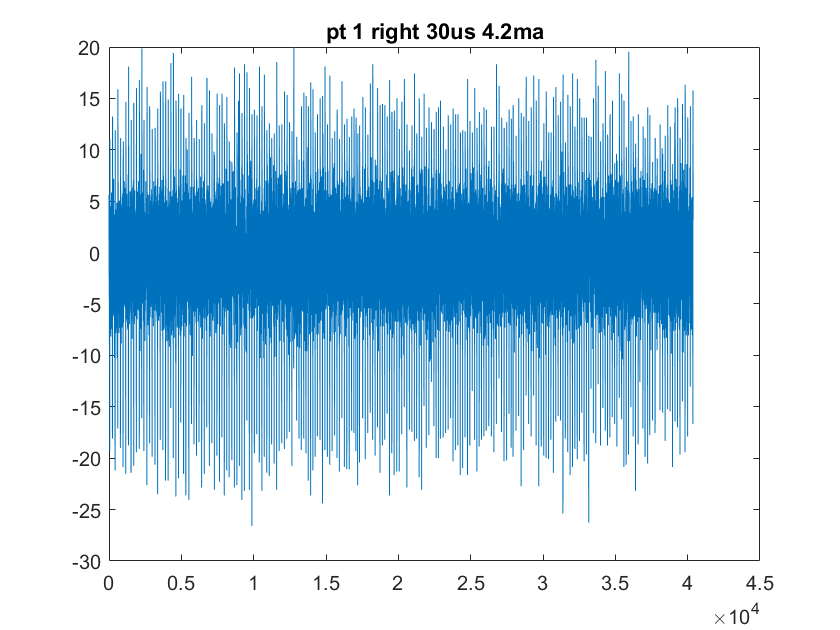

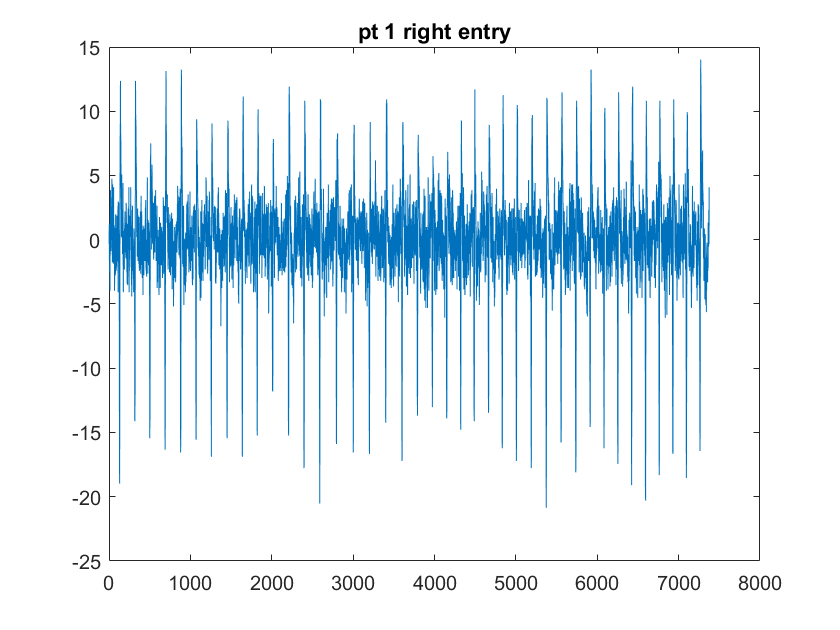

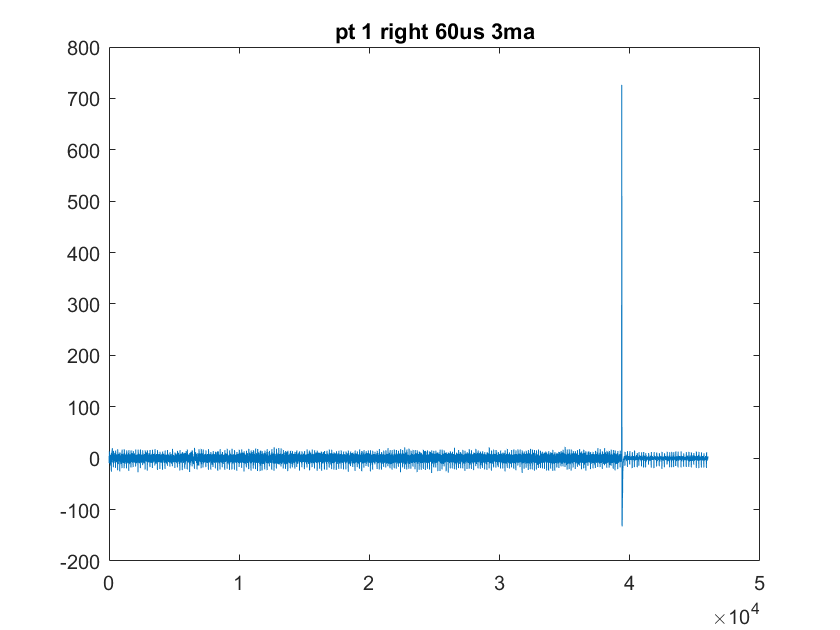

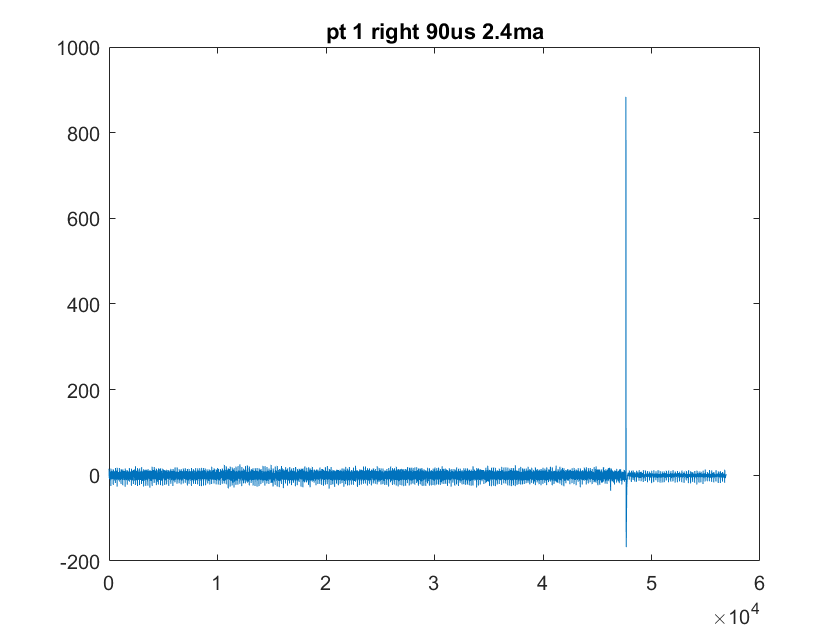

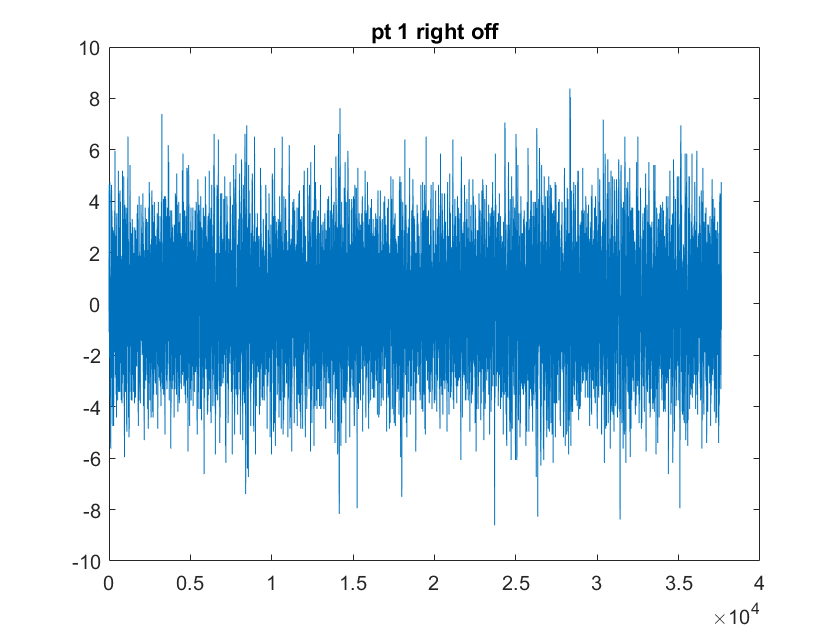

%pt 1 right 
clear all;
figure; 
%get the json 
 cd('C:\Users\sydne\Documents\github\perceive\patientData')
% JAT PC
%cd('C:\Users\Admin\Documents\Github\perceive\patientData')
%
jsonFiles = 'Report_Json_Session_Report_patient1_right_final (1).json'; 
js = jsondecode(fileread(jsonFiles));
%set back to the correct directory 
%Sydnei PC
cd('C:\Users\sydne\Documents\github\perceive\postAnalysis') 
% JAT PC
%cd('C:\Users\Admin\Documents\github\perceive\postAnalysis') 

%% create a struct of the relevant data from brainsense 
leng = numel(js.BrainSenseLfp);
data = struct;
for i=1:leng
    x = num2str(i);
    field = append("treatment", x);
    data.(field).channel = js.BrainSenseLfp(i).Channel;
    data.(field).time = datetime(replace({js.BrainSenseLfp(i).FirstPacketDateTime}, {'T', 'Z'},  {' ', ''}));
    data.(field).pw = js.BrainSenseLfp(i).TherapySnapshot.Right.PulseWidthInMicroSecond;
    data.(field).ma = js.BrainSenseLfp(i).TherapySnapshot.Right.LowerLimitInMilliAmps;
    data.(field).timeDomain = js.BrainSenseTimeDomain(i).TimeDomainData;
end 

%get legend info 
%some parts must be hard coded bc 
for i = 1:leng 
    x = num2str(i);
    field = append("treatment", x);
    pw = num2str(data.(field).pw); 
    ma = num2str(data.(field).ma);
    pt = "pt 1 right "; 
    legendVal{i} = ((append(pt, pw, "us ", ma, "ma")));
end 

%MANUALLY SET THESE BASED UPON THE PATIENT SUMMARY
legendVal{5} = append(pt, "off") ;
legendVal{2} = append(pt, "entry");

for i = 1:leng
    figure
    field = append("treatment", num2str(i));
    plot(data.(field).timeDomain) 
    title(legendVal{i})
    figname = append(legendVal{i}, ".fig"); 
    savefig(figname)
end 

PT1 Left

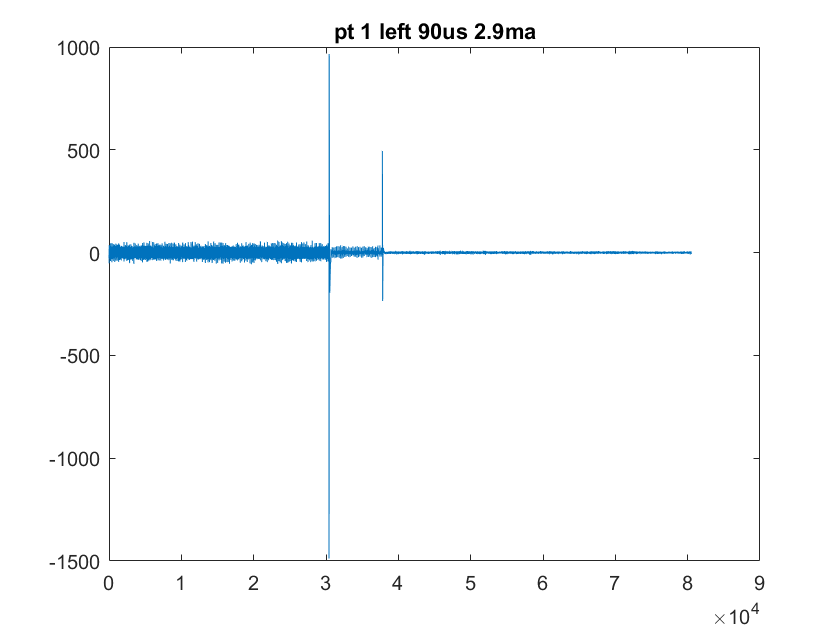

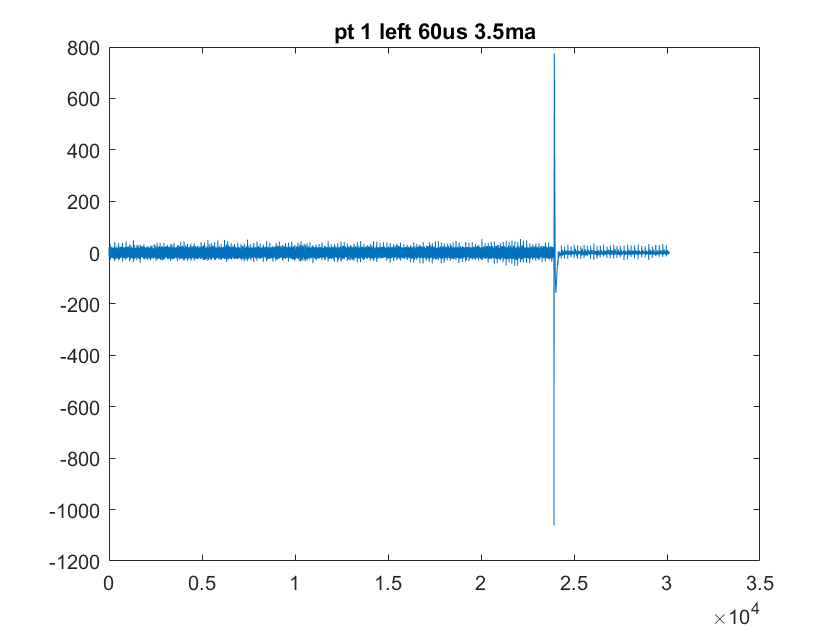

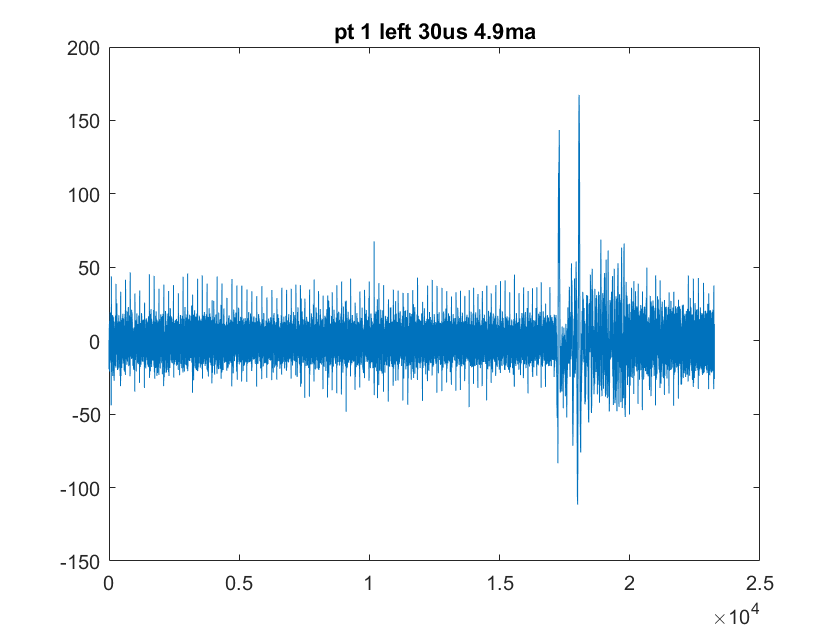

%pt1 left 
clear all;
figure; 
%get the json 
cd('C:\Users\sydne\Documents\github\perceive\patientData')
jsonFiles = 'Report_Json_Session_Report_patient1_left_final (1).json'; 
js = jsondecode(fileread(jsonFiles));
%set back to the correct directory 
cd('C:\Users\sydne\Documents\github\perceive\postAnalysis') 
%% create a struct of the relevant data from brainsense 
leng = numel(js.BrainSenseLfp);
data = struct;
for i=1:leng
    x = num2str(i);
    field = append("treatment", x);
    data.(field).channel = js.BrainSenseLfp(i).Channel;
    data.(field).time = datetime(replace({js.BrainSenseLfp(i).FirstPacketDateTime}, {'T', 'Z'},  {' ', ''}));
    data.(field).pw = js.BrainSenseLfp(i).TherapySnapshot.Left.PulseWidthInMicroSecond;
    data.(field).ma = js.BrainSenseLfp(i).TherapySnapshot.Left.LowerLimitInMilliAmps;
    data.(field).timeDomain = js.BrainSenseTimeDomain(i).TimeDomainData;
end 

%get legend info 
%some parts must be hard coded bc 
for i = 1:leng 
    x = num2str(i);
    field = append("treatment", x);
    pw = num2str(data.(field).pw); 
    ma = num2str(data.(field).ma);
    pt = "pt 1 left "; 
    legendVal{i} = ((append(pt, pw, "us ", ma, "ma")));
end 

%create plot of index vs voltage LFP data 
for i = 1:leng
    figure
    field = append("treatment", num2str(i));
    plot(data.(field).timeDomain) 
    title(legendVal{i})
    figname = append(legendVal{i}, ".fig"); 
    savefig(figname)
end 

PT2 Left

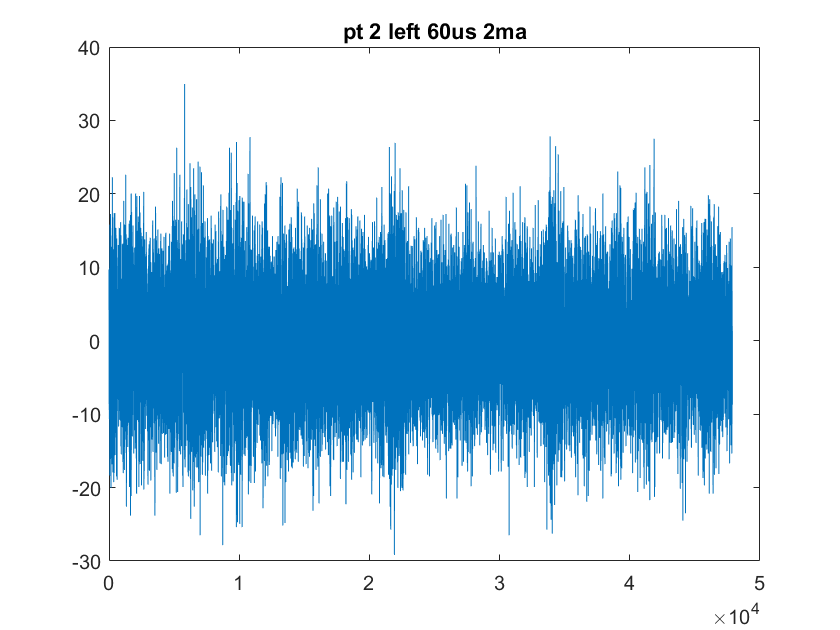

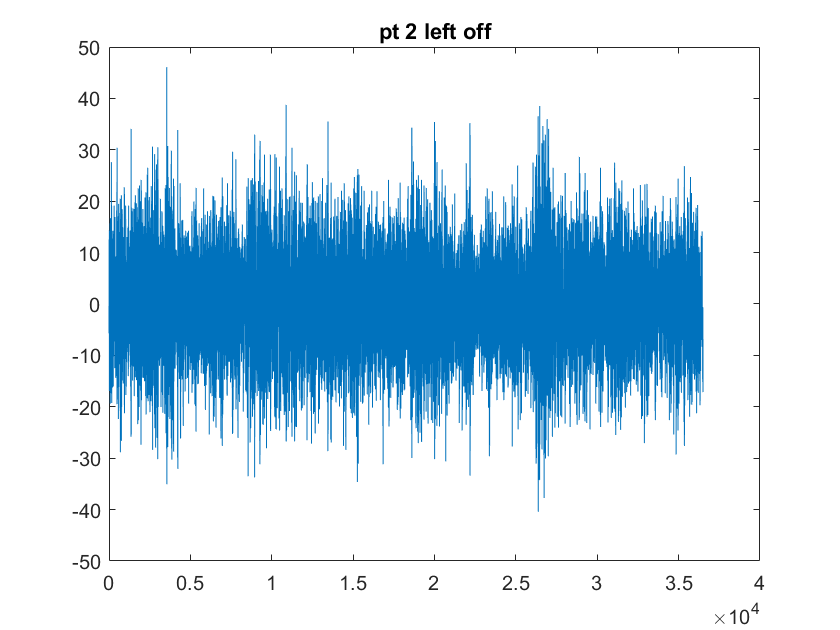

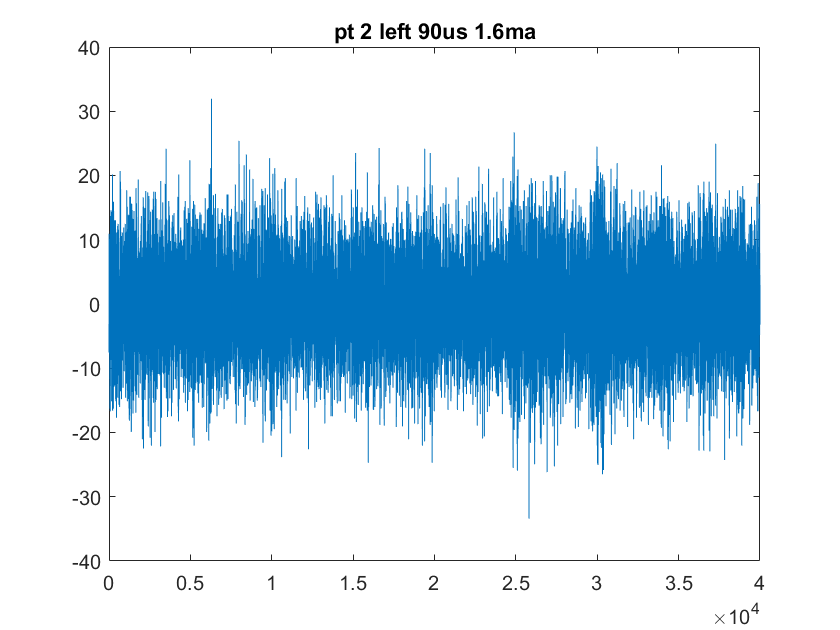

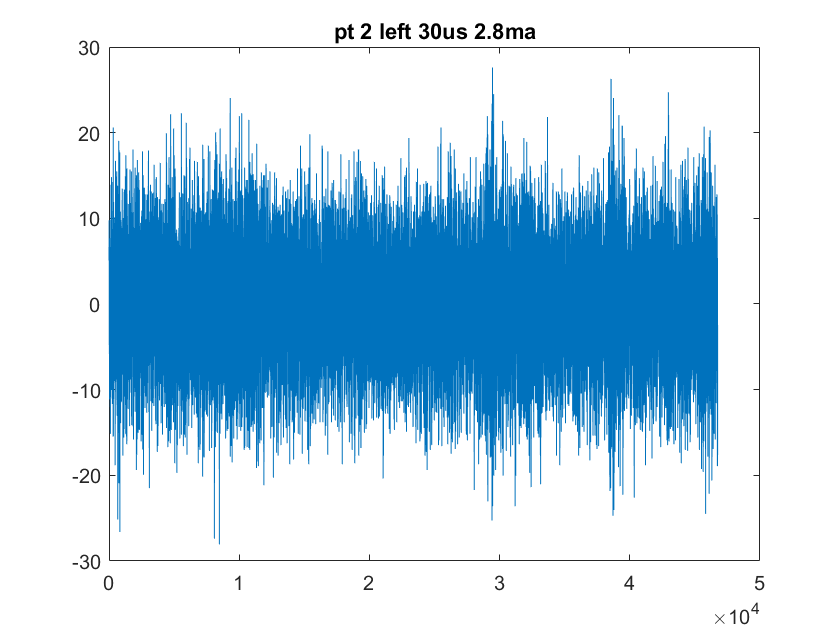

clear all;

%pt 2 has all the data contained in a single JSON due to having a single
%battery 
%this struct gets field 1-4 which contain data for the left 
%and fields 5-8 contains data for the right 
%if errors arise, double check the indexing because it has to be manual 
%in most cases 

%get the json 
 cd('C:\Users\sydne\Documents\github\perceive\patientData')
%cd('C:\Users\Admin\Documents\Github\perceive\patientData\Patient2_0604')
jsonFiles = 'Report_Json_Session_Report_20210604T120025.json'; 
js = jsondecode(fileread(jsonFiles));
%set back to the correct directory 
 cd('C:\Users\sydne\Documents\github\perceive\postAnalysis') 
%cd('C:\Users\Admin\Documents\Github\perceive\postAnalysis')
leng = numel(js.BrainSenseLfp);
data = struct;
for i=1:4
    x = num2str(i);
    field = append("treatment", x);
    data.(field).channel = js.BrainSenseLfp(i).Channel;
    data.(field).time = datetime(replace({js.BrainSenseLfp(i).FirstPacketDateTime}, {'T', 'Z'},  {' ', ''}));
    data.(field).pw = js.BrainSenseLfp(i).TherapySnapshot.Left.PulseWidthInMicroSecond;
    data.(field).ma = js.BrainSenseLfp(i).TherapySnapshot.Left.LowerLimitInMilliAmps;
    data.(field).timeDomain = js.BrainSenseTimeDomain(i).TimeDomainData;
end 

%get legend info 
%some parts must be hard coded bc 
for i = 1:4 
    x = num2str(i);
    field = append("treatment", x);
    pw = num2str(data.(field).pw); 
    ma = num2str(data.(field).ma);
    pt = "pt 2 left "; 
    legendVal{i} = ((append(pt, pw, "us ", ma, "ma")));
end 
%hard code based on clinic notes 
legendVal{2} = append(pt, "off");

%create plot of index vs voltage LFP data 
for i = 1:4
    figure
    field = append("treatment", num2str(i));
    plot(data.(field).timeDomain) 
    title(legendVal{i})
    figname = append(legendVal{i}, ".fig"); 
    savefig(figname)
end 

PT2 Right

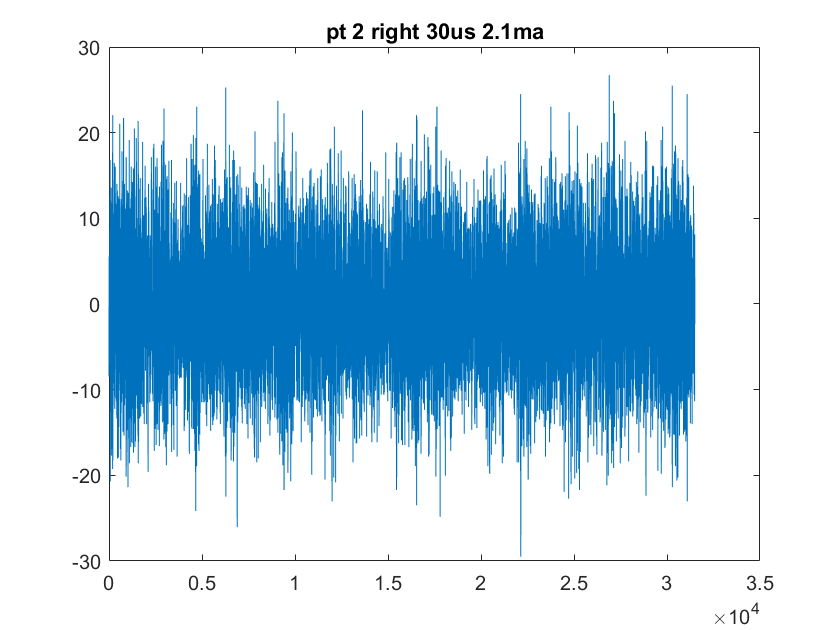

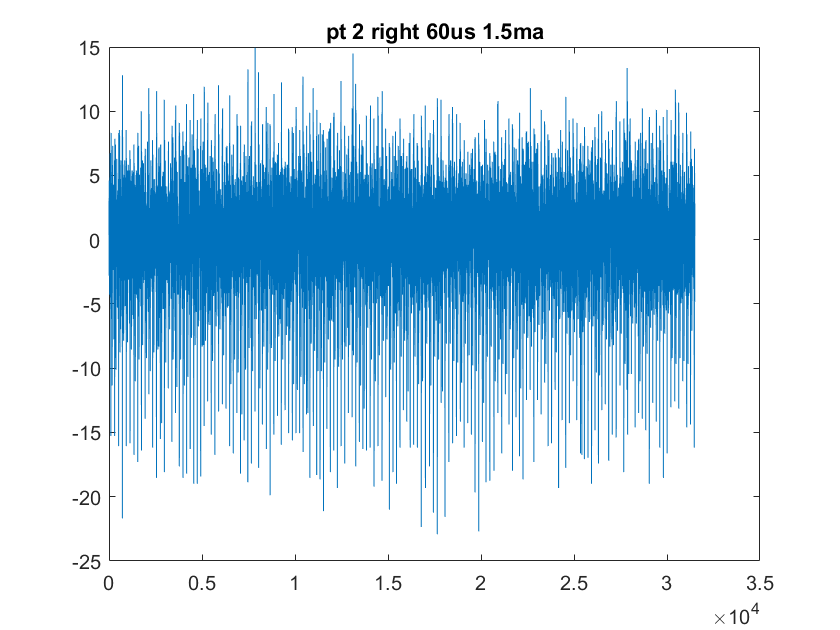

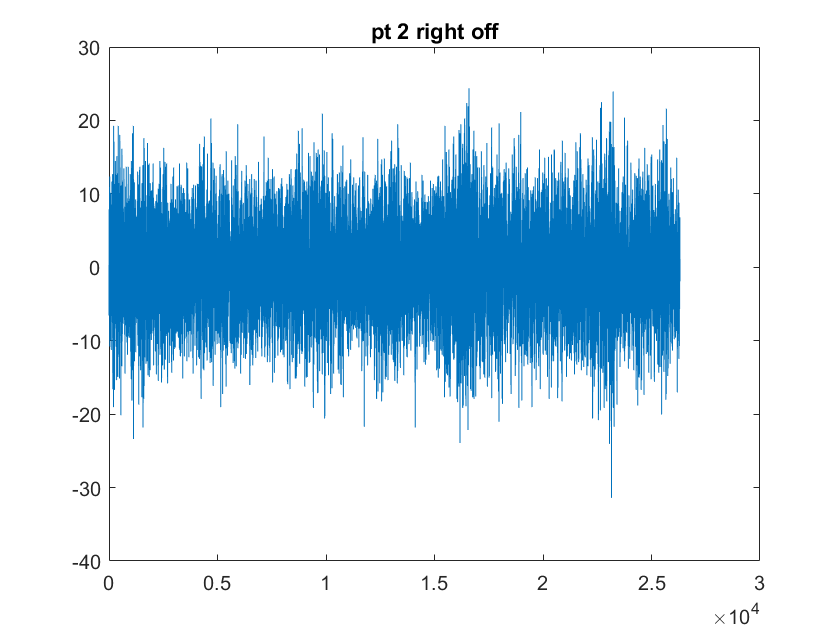

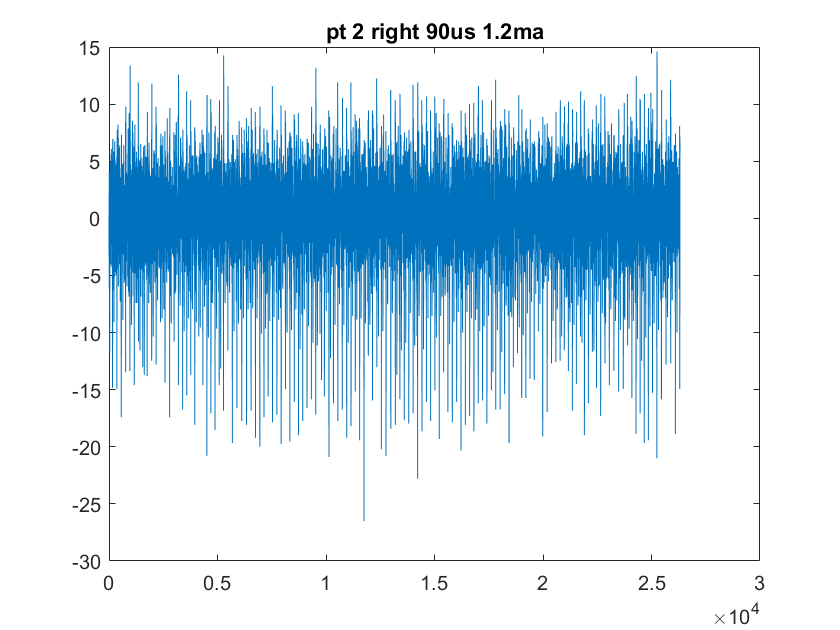

clear all;
%get the json 
cd('C:\Users\sydne\Documents\github\perceive\patientData')
jsonFiles = 'Report_Json_Session_Report_20210604T120025.json'; 
js = jsondecode(fileread(jsonFiles));
%set back to the correct directory 
cd('C:\Users\sydne\Documents\github\perceive\postAnalysis') 

%snapshot
figure;
leng = numel(js.BrainSenseLfp);
data = struct;
for i=5:8
    x = num2str(i);
    field = append("treatment", x);
    data.(field).channel = js.BrainSenseLfp(i).Channel;
    data.(field).time = datetime(replace({js.BrainSenseLfp(i).FirstPacketDateTime}, {'T', 'Z'},  {' ', ''}));
    data.(field).pw = js.BrainSenseLfp(i).TherapySnapshot.Right.PulseWidthInMicroSecond;
    data.(field).ma = js.BrainSenseLfp(i).TherapySnapshot.Right.LowerLimitInMilliAmps;
    data.(field).timeDomain = js.BrainSenseTimeDomain(i).TimeDomainData;
end  

%get legend info 
%some parts must be hard coded bc 
for i=5:8
    x = num2str(i);
    field = append("treatment", x);
    pw = num2str(data.(field).pw); 
    ma = num2str(data.(field).ma);
    pt = "pt 2 right "; 
    legendVal{i} = ((append(pt, pw, "us ", ma, "ma")));
end 
%need to investigate discrepency between json and pdf summary
legendVal{7} = append(pt, "off"); 

%create plot of index vs voltage LFP data 
for i = 5:8
    figure
    field = append("treatment", num2str(i));
    plot(data.(field).timeDomain) 
    title(legendVal{i})
    figname = append(legendVal{i}, ".fig"); 
    savefig(figname)
end 

PT3 Right

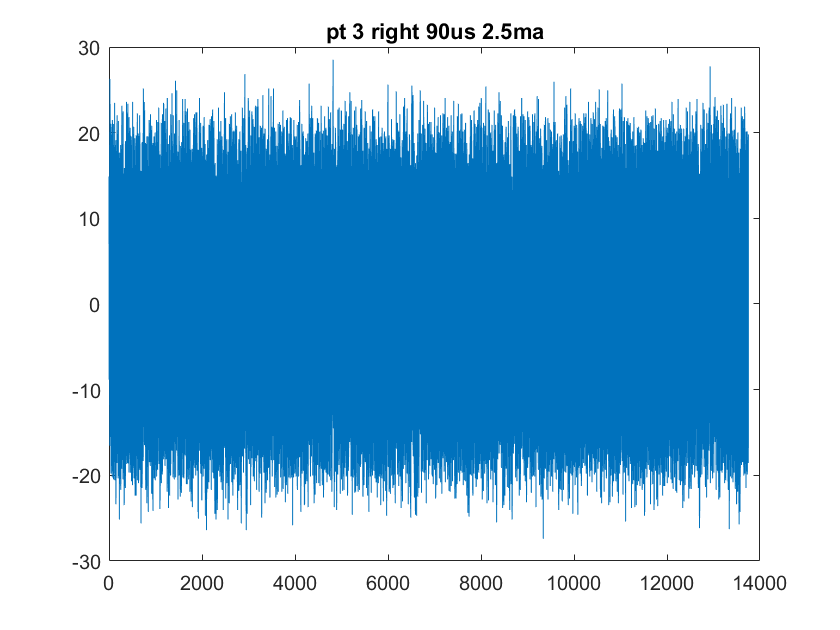

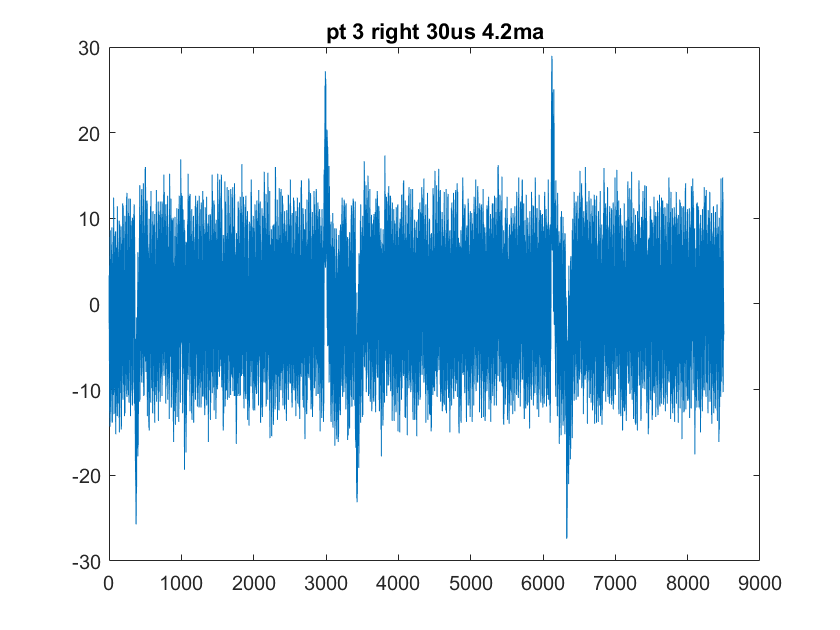

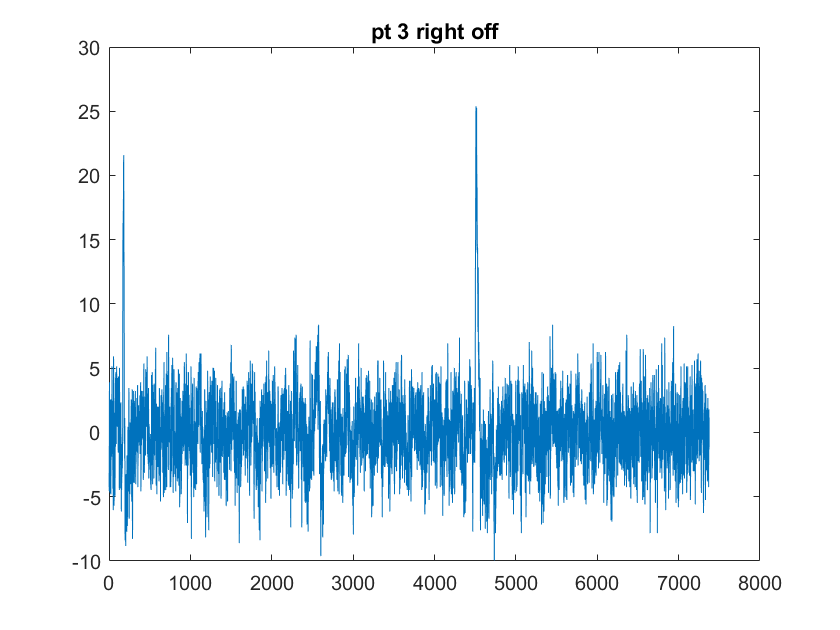

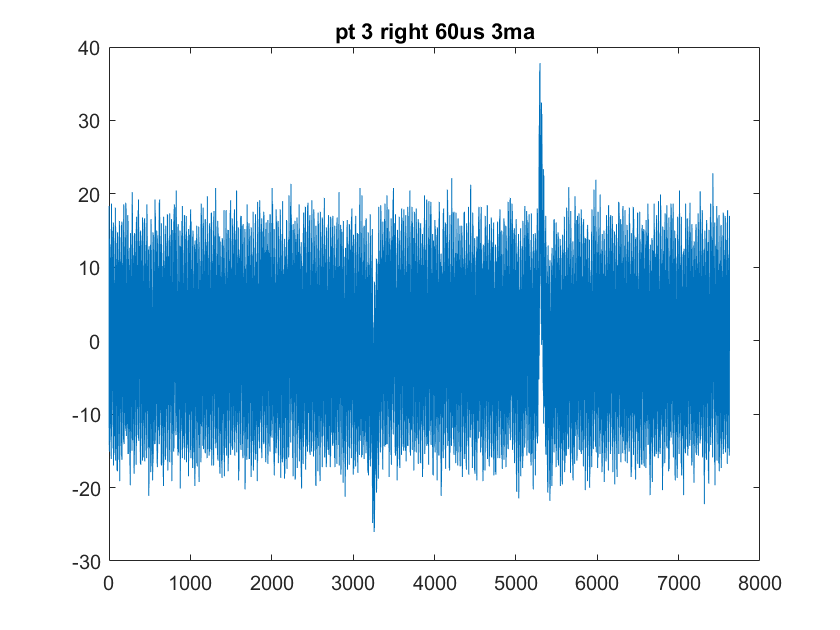

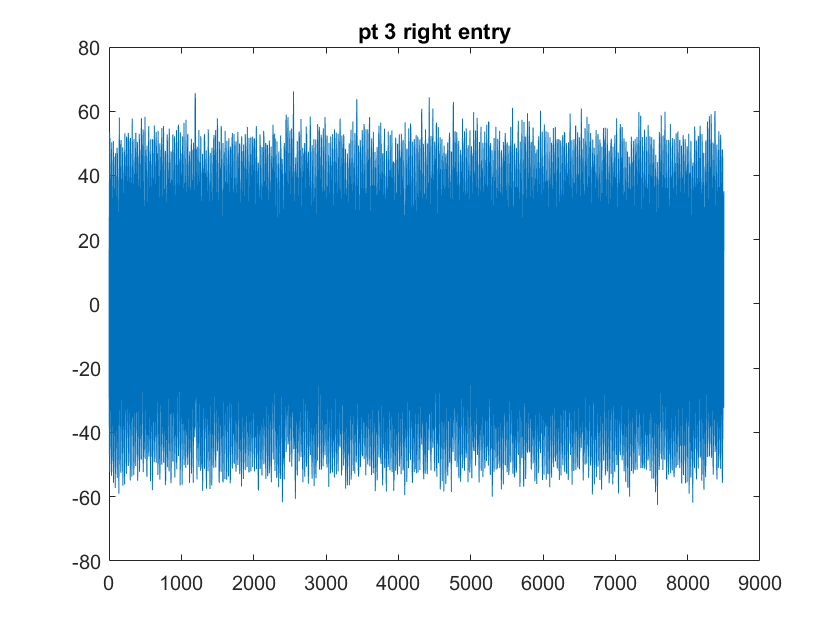

clear all;
figure;
%get the json 
cd('C:\Users\sydne\Documents\github\perceive\patientData\Patient3_0630')
jsonFiles = 'Report_Json_Session_Report_patient3_right_final.json'; 
js = jsondecode(fileread(jsonFiles));
%set back to the correct directory 
cd('C:\Users\sydne\Documents\github\perceive\postAnalysis') 
%% create a struct of the relevant data from brainsense 
leng = numel(js.BrainSenseLfp);
data = struct;
for i=1:leng
    x = num2str(i);
    field = append("treatment", x);
    data.(field).channel = js.BrainSenseLfp(i).Channel;
    data.(field).time = datetime(replace({js.BrainSenseLfp(i).FirstPacketDateTime}, {'T', 'Z'},  {' ', ''}));
    data.(field).pw = js.BrainSenseLfp(i).TherapySnapshot.Right.PulseWidthInMicroSecond;
    data.(field).ma = js.BrainSenseLfp(i).TherapySnapshot.Right.LowerLimitInMilliAmps;
    data.(field).timeDomain = js.BrainSenseTimeDomain(i).TimeDomainData;
end  

%get legend info 
%some parts must be hard coded bc 
for i = 1:leng 
    x = num2str(i);
    field = append("treatment", x);
    pw = num2str(data.(field).pw); 
    ma = num2str(data.(field).ma);
    pt = "pt 3 right "; 
    legendVal{i} = ((append(pt, pw, "us ", ma, "ma")));
end 
legendVal{3} = append(pt, "off");
legendVal{5} = append(pt, "entry"); 

%create plot of index vs voltage LFP data 
for i = 1:leng
    figure
    field = append("treatment", num2str(i));
    plot(data.(field).timeDomain) 
    title(legendVal{i})
    figname = append(legendVal{i}, ".fig"); 
    savefig(figname)
end 

PT3 Left

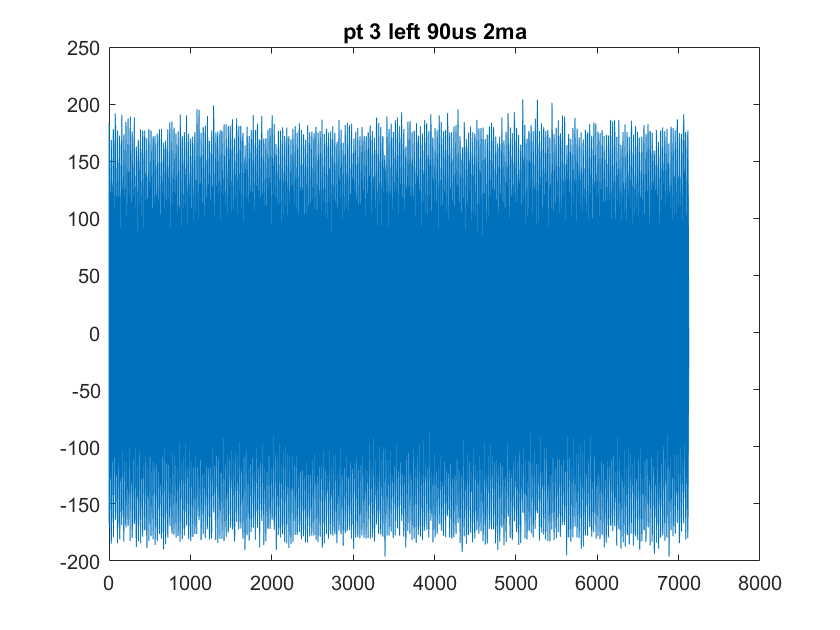

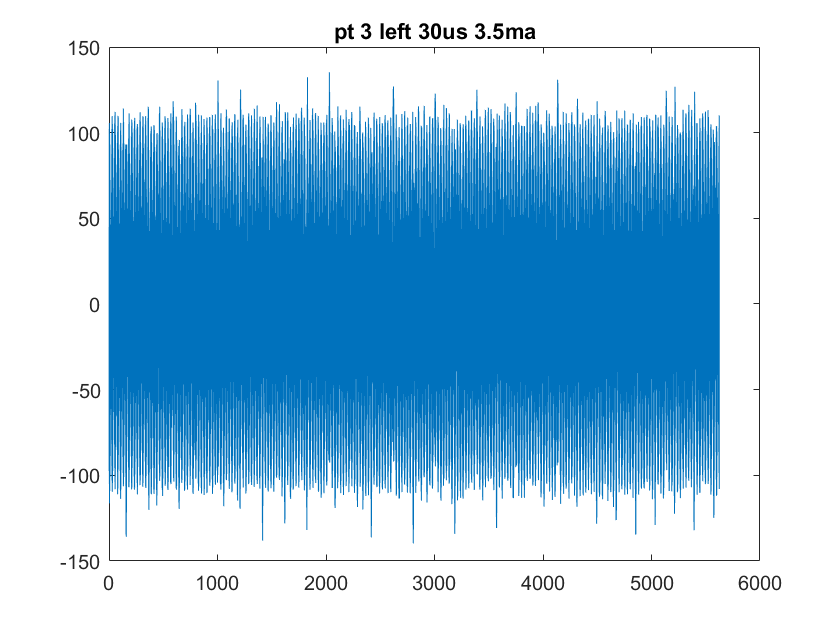

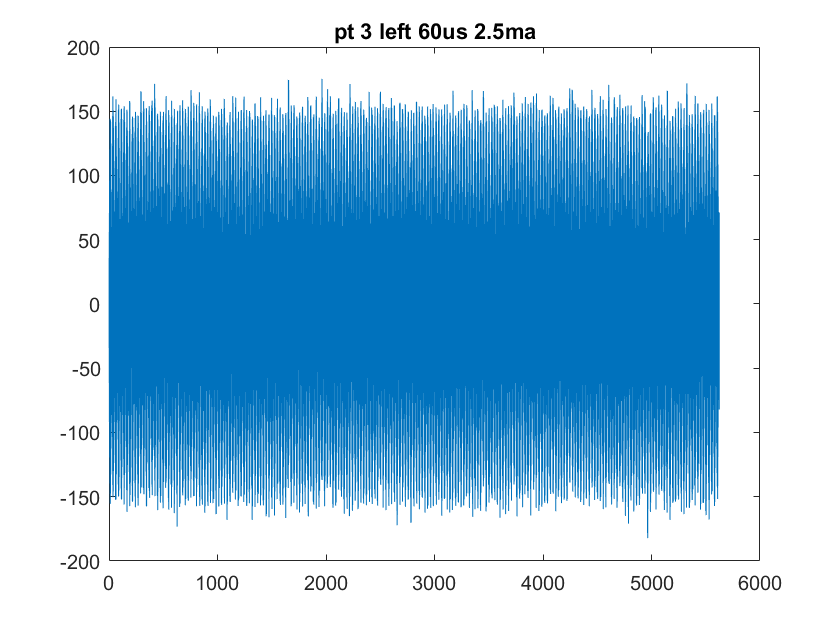

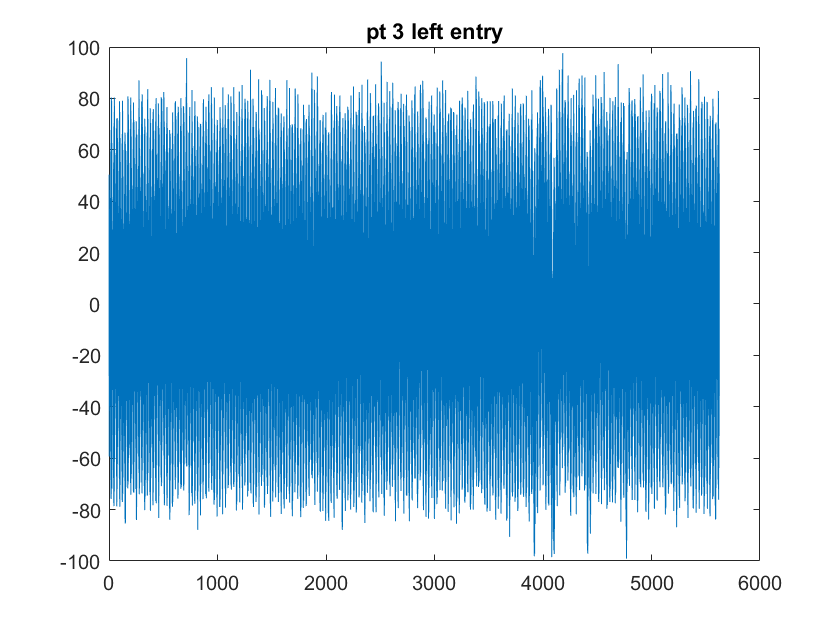

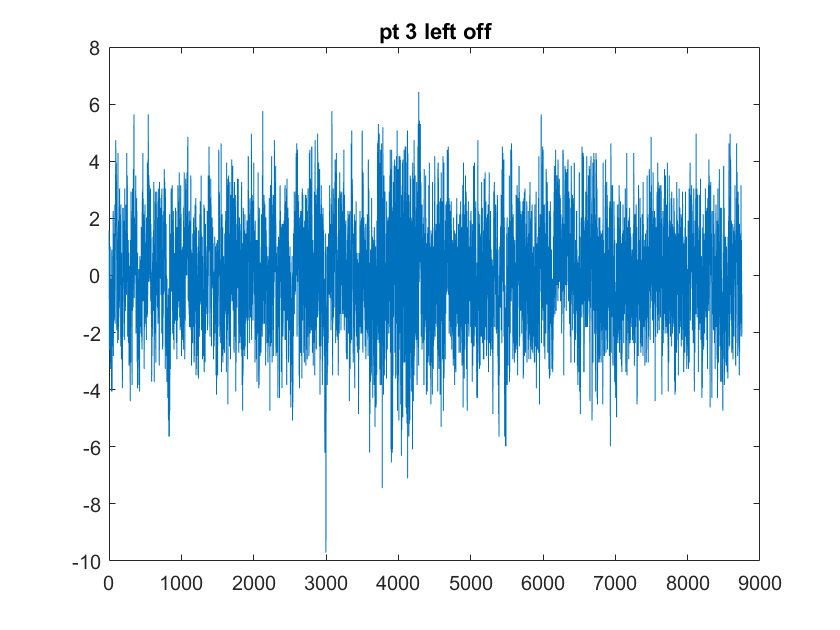

clear all;
figure;
%get the json 
cd('C:\Users\sydne\Documents\github\perceive\patientData')
jsonFiles = 'Report_Json_Session_Report_Patient3_left_final.json'; 
js = jsondecode(fileread(jsonFiles));
%set back to the correct directory 
cd('C:\Users\sydne\Documents\github\perceive\postAnalysis') 
%% create a struct of the relevant data from brainsense 
leng = numel(js.BrainSenseLfp);
data = struct;
for i=1:leng
    x = num2str(i);
    field = append("treatment", x);
    data.(field).channel = js.BrainSenseLfp(i).Channel;
    data.(field).time = datetime(replace({js.BrainSenseLfp(i).FirstPacketDateTime}, {'T', 'Z'},  {' ', ''}));
    data.(field).pw = js.BrainSenseLfp(i).TherapySnapshot.Left.PulseWidthInMicroSecond;
    data.(field).ma = js.BrainSenseLfp(i).TherapySnapshot.Left.LowerLimitInMilliAmps;
    data.(field).timeDomain = js.BrainSenseTimeDomain(i).TimeDomainData;
end

%get legend info 
%some parts must be hard coded bc 
for i = 1:leng 
    x = num2str(i);
    field = append("treatment", x);
    pw = num2str(data.(field).pw); 
    ma = num2str(data.(field).ma);
    pt = "pt 3 left "; 
    legendVal{i} = ((append(pt, pw, "us ", ma, "ma")));
end 
legendVal{4} = append(pt, "entry");
legendVal{5} = append(pt, "off"); 

%create plot of index vs voltage LFP data 
for i = 1:leng
    figure
    field = append("treatment", num2str(i));
    plot(data.(field).timeDomain) 
    title(legendVal{i})
    figname = append(legendVal{i}, ".fig"); 
    savefig(figname)
end 

### Code to Create Plot of all Data 

Run the section of interest above using "run section" to generate relevant data 

Run this section to plot all of the raw LFP data on the same plot 

% figure
% for i = 1:leng
%     field = append("treatment", num2str(i));
%     [outDAT] = proc1(data.(field).timeDomain); 
%     %collect time domain data from given field in Data strcut I made 
% 
%     hold on
%     plot(outDAT.freq,outDAT.pwr)
% end
% legend()

### Code to Plot Raw Data

Run the section of interest above using "run section" to generate relevant data 

Run this section using "run section" to create index vs voltage for given time domain data 

% figure
% for i = 1:leng 
%     field = append("treatment", num2str(i));
%     plot(data.(field).timeDomain) 
%     figure
% end 

function [outDAT] = proc1(dataIN)
%purpose of this fucntion is really to proces the data in a
%general and nonspecific way 

hp = highpass(dataIN,0.8,250);
lp = lowpass(hp,59,250);
%dont recall how these numbers were created 
[x,y] = pspectrum(lp,250,'FrequencyLimits',[1 59]);

xl = 10*log10(x);
%plots bode-ish of power from pspectrum
x2 = smoothdata(xl,'gaussian',150);
%smooth the bode 

outDAT.freq = y;
outDAT.pwr = x2;

end